BEREN ÜNVEREN 221101006 ELE 371 PROJESI

İKİNCİ KISIM

1) 

studentId = 221101006;
rng(studentId);

a = randi(4);
b = randi(4);
c = randi(4);
d = randi(4);
e = randi(4);
f = randi(4);

fprintf('a = %d\n', a);

a = 1


fprintf('b = %d\n', b);

b = 3


fprintf('c = %d\n', c);

c = 2


fprintf('d = %d\n', d);

d = 4


fprintf('e = %d\n', e);

e = 1


fprintf('f = %d\n', f);

f = 2


 2) T = a + b + c + d + e + f  temel dönemli x(t) sinyali çıkarımı:

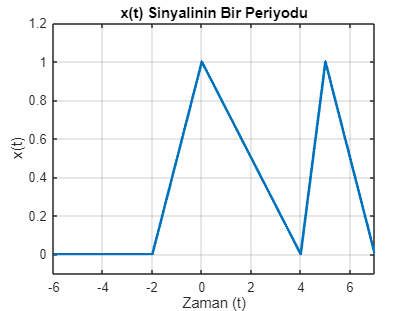

dt = 0.01;
t = -a-b-c:dt:d+e+f;
xt = zeros(size(t));
idx = 1:length(t);
xt(idx)=(((t(idx)>=-c & t(idx)<0) .* ((1/c)*t(idx)+1)) + ... %x(t)=(1/c)t+1
        ((t(idx)>=0 & t(idx)<d) .* ((-1/d)*t(idx)+1)) + ... %x(t)=(-1/d)t+1
        ((t(idx)>=d & t(idx)<d+e) .* ((1/e)*(t(idx)-d))) + ... %x(t)=(1/e)(t-d)
        ((t(idx)>=d+e & t(idx)<=d+e+f) .* (1-(1/f)*(t(idx)-(d+e)))) ... %x(t)=(1/f)(t-d-e)
        );

figure;
plot(t, xt, 'LineWidth', 2);
title('x(t) Sinyalinin Bir Periyodu');
xlabel('Zaman (t)');
ylabel('x(t)');
grid on;
ylim([-0.1 1.2]);
xlim([-a-b-c d+e+f])

3) x(t) Fourier katsayıları: abs(ak) k'ya göre, k=-30,30 için stem komutu ile, a0 ve k!=0 hesabı ayrı. analiz ve grafik.

ak = (1/T) ∫ x(t)e^(-jkω₀t) dt  -> burada parcalı integral olacak

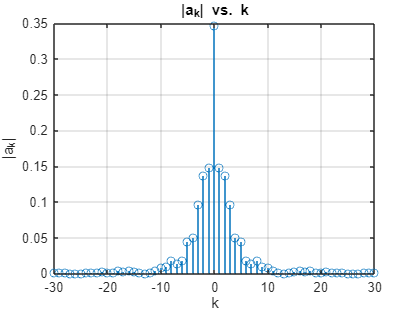

T = a+b+c+d+e+f;
w0 = 2*pi/T;
integrand = @(t, k)(((t>=-c & t<0) .* ((1/c)*t+1)) + ... %x(t)=(1/c)t+1
                    ((t>=0 & t<d) .* ((-1/d)*t+1)) + ... %x(t)=(-1/d)t+1
                    ((t>=d & t<d+e) .* ((1/e)*(t-d))) + ... %x(t)=(1/e)(t-d)
                    ((t>=d+e & t<=d+e+f) .* (1-(1/f)*(t-(d+e)))) ... %x(t)=(1/f)(t-d-e)
                    ).* exp(-1j*k*w0*t);
k_vals = -30:30;
ak = zeros(size(k_vals));
ak(k_vals == 0) = (0.5 * (c+d) + 0.5 * (e+f))/T; %ak=0 durumu
k_nonzero_indices = find(k_vals ~= 0);

for i = 1:length(k_nonzero_indices)
    idx = k_nonzero_indices(i);
    ki = k_vals(idx);
    integral_result = integral(@(t) integrand(t, ki), -c, d+e+f);
    ak(idx) = (1/T) * integral_result;
end

figure;
stem(k_vals, abs(ak));
title('|a_k| vs. k');
xlabel('k');
ylabel('|a_k|');

grid on;
xlim([-30 30]);

4) x(t) sinyalinin 1 dönemi 0.01s aralıklarla t = -a-b-c:dt:d+e+f içinde zaman

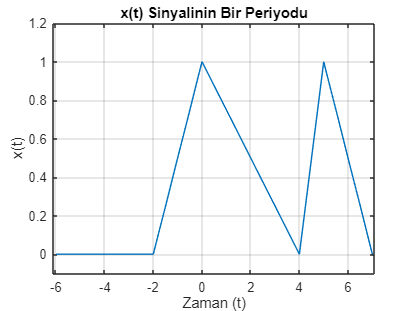

delta_t = 0.01;
zaman = (-a - b - c) : delta_t : (d + e + f);
xt = zeros(size(zaman));

xt = (((zaman >= -c & zaman < 0) .* ((1/c)*zaman + 1)) + ... %(1/c)t+1
      ((zaman >= 0 & zaman < d) .* ((-1/d)*zaman + 1)) + ... %(-1/d)t+1
      ((zaman >= d & zaman < d + e) .* ((1/e)*(zaman - d))) + ... %(1/e)(t-d)
      ((zaman >= d + e & zaman <= d + e + f) .* (1 - (1/f)*(zaman - (d + e)))) ... %1-(1/f)(t-d-e)
     );

figure;
plot(zaman, xt);
title('x(t) Sinyalinin Bir Periyodu');
xlabel('Zaman (t)');
ylabel('x(t)');
grid on;
ylim([-0.1 1.2]);
xlim([-a - b - c - 0.1, d + e + f + 0.1]);

5) Fourier ile yakınsama

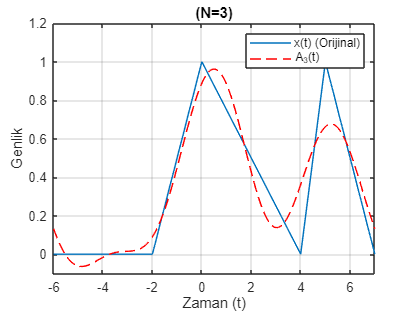

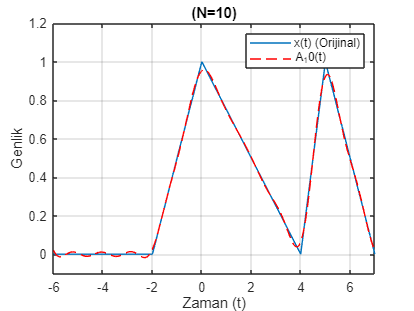

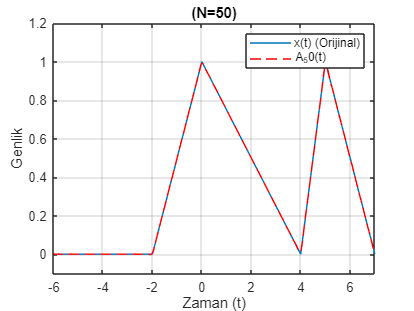

k_vals_new = -50:50;
ak_new = zeros(size(k_vals_new));
ak_new(k_vals_new == 0) = (0.5 * (c+d+e+f)) / T;

k_nonzero_indices_new = find(k_vals_new ~= 0);
for i = 1:length(k_nonzero_indices_new)
    idx = k_nonzero_indices_new(i);
    ki = k_vals_new(idx);
    integral_result = integral(@(t_val) integrand(t_val, ki), -c, d+e+f);
    ak_new(idx) = (1/T) * integral_result;
end

Ns = [3, 10, 50];
for N = Ns
    AN_t = zeros(size(t));
    current_k_indices = (k_vals_new >= -N & k_vals_new <= N);
    current_k_vals = k_vals_new(current_k_indices);
    current_ak = ak_new(current_k_indices);

    for k_idx = 1:length(current_k_vals)
        k_val = current_k_vals(k_idx);
        ak_val = current_ak(k_idx);
        AN_t = AN_t + ak_val * exp(1j * k_val * w0 * t);
    end

    figure;
    plot(t, xt);
    hold on;
    plot(t, real(AN_t), 'r--');
    hold off;
    title(sprintf('(N=%d)', N));
    xlabel('Zaman (t)');
    ylabel('Genlik');
    legend('x(t) (Orijinal)', sprintf('A_%d(t)', N));
    grid on;
    ylim([-0.1 1.2]);
    xlim([-a-b-c d+e+f]);
end

ÜÇÜNCÜ KISIM

1) 

studentId = 221101006;
rng(studentId)
a = randi(10);
b = a+randi(10);
c = randi(10);

fprintf('a = %d\n', a);

a = 3


fprintf('b = %d\n', b);

b = 9


fprintf('c = %d\n', c);

c = 4


2) h1(t) = sinc(at), h2(t) = sinc(bt) − sinc(at) ve h3(t) = sinc(at) cos(ct) sinyallerini t ∈ (−50, 50)

zaman aralığında ve zaman ekseninde 0.01 saniye aralıklarla sinyallerden örnekler alarak Matlab’da

plot komutunu kullanarak ayrı ayrı grafiklerde çizim:

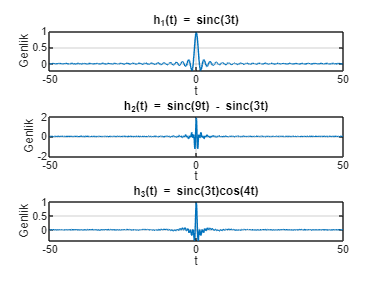

function result = sinc(val_t, val_a)
    result = zeros(size(val_t)); 
    zero_indices = (val_t == 0);
    result(zero_indices) = val_a / pi;
    non_zero_indices = (val_t ~= 0);
    result(non_zero_indices) = sin(val_a * val_t(non_zero_indices)) ./ (pi * val_t(non_zero_indices));
end

t_sinc = -50:0.01:50; 
h1_t = sinc(t_sinc, a);
h2_t = sinc(t_sinc, b) - sinc(t_sinc, a);
h3_t = sinc(t_sinc, a) .* cos(c * t_sinc);

figure;
subplot(3,1,1);
plot(t_sinc, h1_t);
title(sprintf('h_1(t) = sinc(%dt)', a));
xlabel('t'); ylabel('Genlik'); grid on; xlim([-50 50]);

subplot(3,1,2);
plot(t_sinc, h2_t);
title(sprintf('h_2(t) = sinc(%dt) - sinc(%dt)', b, a));
xlabel('t'); ylabel('Genlik'); grid on; xlim([-50 50]);

subplot(3,1,3);
plot(t_sinc, h3_t);
title(sprintf('h_3(t) = sinc(%dt)cos(%dt)', a, c));
xlabel('t'); ylabel('Genlik'); grid on; xlim([-50 50]);

3) h1_t, h2_t, h3_t CTFTleri ve magnitudeları:

FT { sin(A*t) / (pi*t) } = rect(ω / (2A)) h1 icin

h2 FT icin FT(sinc(bt))-FT(sinc(at)) 

h3 icin normalde iki fonk carpımıysa FTde konva karsılık gelir deriz

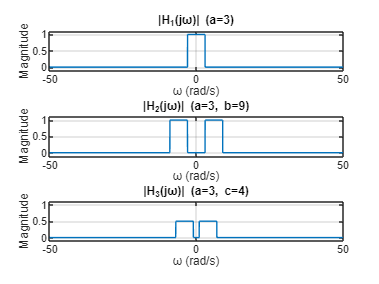

w_vals = -50:0.01:50; 

H1_jw = zeros(size(w_vals));
H1_jw(abs(w_vals) < a) = 1;

H2_jw = zeros(size(w_vals)); 
H2_jw(abs(w_vals) < b) = 1;
H2_jw(abs(w_vals) == b) = 0.5;
H2_jw(abs(w_vals) < a) = H2_jw(abs(w_vals) < a) - 1;
H2_jw(abs(w_vals) == a) = H2_jw(abs(w_vals) == a) - 0.5;

H3_jw = zeros(size(w_vals)); 
H3_jw(abs(w_vals - c) < a) = H3_jw(abs(w_vals - c) < a) + 0.5;
H3_jw(abs(w_vals - c) == a) = H3_jw(abs(w_vals - c) == a) + 0.25;
H3_jw(abs(w_vals + c) < a) = H3_jw(abs(w_vals + c) < a) + 0.5;
H3_jw(abs(w_vals + c) == a) = H3_jw(abs(w_vals + c) == a) + 0.25;

figure;
subplot(3,1,1);
plot(w_vals, abs(H1_jw));
title(sprintf('|H_1(jω)| (a=%d)', a));
xlabel('ω (rad/s)');
ylabel('Magnitude');
grid on;
xlim([-50 50]);
ylim([-0.1 1.1]); 
subplot(3,1,2);
plot(w_vals, abs(H2_jw));
title(sprintf('|H_2(jω)| (a=%d, b=%d)', a, b));
xlabel('ω (rad/s)');
ylabel('Magnitude');
grid on;
xlim([-50 50]);
ylim([-0.1 1.1]);
subplot(3,1,3);
plot(w_vals, abs(H3_jw));
title(sprintf('|H_3(jω)| (a=%d, c=%d)', a, c));
xlabel('ω (rad/s)');
ylabel('Magnitude');
grid on;
xlim([-50 50]);
ylim([-0.1 1.1]);

`4) h4(t) = h1(t)h2(t) ve h5(t) = h2(t) ∗ h3(t) CTFTleri ve magnitudeları: *frekans ekseninde 0.01 radyan/saniye aralıklarla fonksiyonlardan örnekler alın*  H4 DE KAFAM KARISTI`

h4 için h1 h2 konv

h5 için h2 ve h3 çarpım

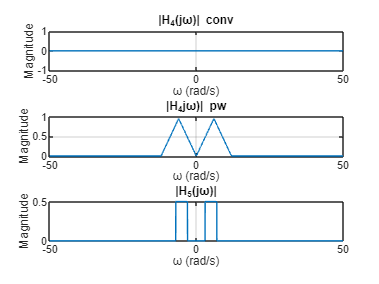

H4_jw_conv = (1/(2*pi)) * conv(H1_jw, H2_jw, 'same') * (w_vals(2)-w_vals(1));
H4_jw_pointwise = H1_jw .* H2_jw;
H5_jw = H2_jw .* H3_jw;

% muhtemelen H4(jw) = (1/(2pi)) * (H1(jw) * H2(jw)) evrişimi bekleniyor.

figure;
subplot(3,1,1);
plot(w_vals, abs(H4_jw_pointwise));
title('|H_4(jω)| conv');
xlabel('ω (rad/s)'); ylabel('Magnitude'); grid on; xlim([-50 50]);
subplot(3,1,2);
plot(w_vals, abs(H4_jw_conv));
title('|H_4jω)| pw');
xlabel('ω (rad/s)'); ylabel('Magnitude'); grid on; xlim([-50 50]);
subplot(3,1,3);
plot(w_vals, abs(H5_jw));
title('|H_5(jω)|');
xlabel('ω (rad/s)'); ylabel('Magnitude'); grid on; xlim([-50 50]);

5) fft - fftshift ile CTFT

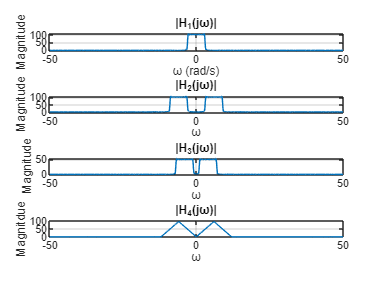

Ts = 0.01;
t_fft = -10:Ts:10-Ts; 
% N = 4096'ya zero-padding yap

h1_t_fft = sinc(t_fft, a);
N_fft = 4096;
h1_t_padded = [h1_t_fft, zeros(1, N_fft - length(h1_t_fft))];

H1_k = fft(h1_t_padded);
H1_k_shifted = fftshift(H1_k);

% k=1,2,...,N. w = 2*pi*(k-1)/(N*Ts)
% fftshift sonrası k ekseni -N/2'den N/2-1'e gider.
% w = 2*pi * ((-N_fft/2):(N_fft/2-1)) / (N_fft * Ts);
% dw = (2*pi/T_total), where T_total = N_fft * Ts
% w_fft = (2*pi/ (N_fft*Ts)) * ((-N_fft/2):(N_fft/2-1));
Fs_fft = 1/Ts;
w_fft = linspace(-pi*Fs_fft, pi*Fs_fft - (2*pi*Fs_fft)/N_fft, N_fft);

figure;
subplot(4,1,1); plot(w_fft, abs(H1_k_shifted)); title('|H_1(jω)|'); xlabel('ω (rad/s)'); ylabel('Magnitude'); grid on; xlim([-50 50]);

h2_t_fft = sinc(t_fft, b) - sinc(t_fft, a);
h3_t_fft = sinc(t_fft, a) .* cos(c * t_fft);
h4_t_fft = h1_t_fft .* h2_t_fft;

H2_k = fft(h2_t_fft, N_fft); H2_k_shifted = fftshift(H2_k);
H3_k = fft(h3_t_fft, N_fft); H3_k_shifted = fftshift(H3_k);
H4_k = fft(h4_t_fft, N_fft); H4_k_shifted = fftshift(H4_k);

subplot(4,1,2); plot(w_fft, abs(H2_k_shifted)); title('|H_2(jω)|'); xlabel('ω'); ylabel('Magnitude'); grid on; xlim([-50 50]);
subplot(4,1,3); plot(w_fft, abs(H3_k_shifted)); title('|H_3(jω)|'); xlabel('ω'); ylabel('Magnitude'); grid on; xlim([-50 50]);
subplot(4,1,4); plot(w_fft, abs(H4_k_shifted)); title('|H_4(jω)|'); xlabel('ω'); ylabel('Magnitdue'); grid on; xlim([-50 50]);

DÖRDÜNCÜ KISIM

studentId = 221101006;
rng(studentId)
a = 2+randi(8);
b = 2+randi(8);
c = 2+randi(8);

2) DZD ayrık zaman sistemde : 

y[n] = −(1/a)y[n − 1] + (1/b)y[n − 2] + (1/c)x[n]. 

x[n] = δ[n] için recursive elde edilecek y[n] kodu:

h[n] = -(1/a)h[n-1] + (1/b)h[n-2] + (1/c)δ[n] 

recursion base case: h[-1] = 0; h[-2] = 0.

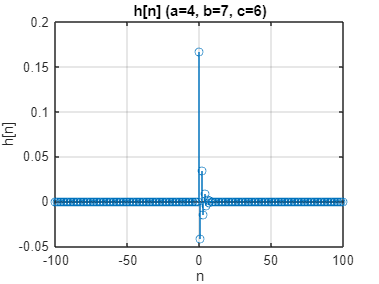

n_start = -100;
n_end = 100;
n_vals = n_start:n_end; 
h_n = zeros(size(n_vals)); 
idx_0 = find(n_vals == 0);
h_n(idx_0) = 1 / c;
if (idx_0 + 1) <= length(n_vals)
    h_n(idx_0 + 1) = -(1 / a) * h_n(idx_0);
end

for k = (idx_0 + 2):length(n_vals)
    h_n(k) = -(1 / a) * h_n(k-1) + (1 / b) * h_n(k-2);
end

figure;
stem(n_vals, h_n);
title(sprintf('h[n] (a=%d, b=%d, c=%d)', a, b, c));
xlabel('n');
ylabel('h[n]');
grid on;
xlim([-100 100]);

3) Yukarıdaki eşitliği frekans uzayına alarak (ayrık zaman Fourier dönüşümü) sistemin frekans yanıtını H(e^jw)’yı teorik olarak elde edin. Frekans yanıtının  grafiğini w ∈ (−π,π) için 0.01 radyan/saniye aralıklarla Matlab’da plot  komutunu kullanarak çizdirin. Frekans yanıtını kısmi kesirlere ayrıştırıp (partial fraction expansion) ters Fourier dönüşümü uygulayarak dürtü yanıtını elde edin.

y[n] = -(1/a)y[n-1] + (1/b)y[n-2] + (1/c)x[n]

DTFT{x[n-k]} = X(e^jw)e^(-jwk))

DTFT{y[n]} = DTFT{-(1/a)y[n-1]} + DTFT{(1/b)y[n-2]} + DTFT{(1/c)x[n]}

Y(e^jw) = -(1/a)Y(e^jw)e^(-jw) + (1/b)Y(e^jw)e^(-j2w) + (1/c)X(e^jw)

Y(e^jw) + (1/a)Y(e^jw)e^(-jw) - (1/b)Y(e^jw)e^(-j2w) = (1/c)X(e^jw)

Y(e^jw) [1 + (1/a)e^(-jw) - (1/b)e^(-j2w)] = (1/c)X(e^jw)

H(e^jw) = Y(e^jw) / X(e^jw) = (1/c) / [1 + (1/a)e^(-jw) - (1/b)e^(-j2w)]

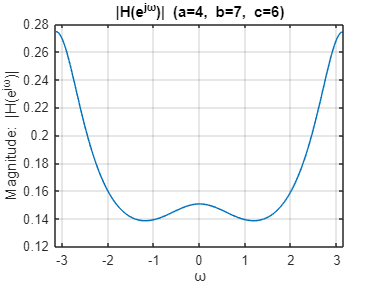

w_dtft = -pi:0.01:pi;
numerator = (1/c);
denominator = (1 + (1/a) * exp(-1j*w_dtft) - (1/b) * exp(-1j*2*w_dtft));
H_ejw = numerator ./ denominator;

figure;
plot(w_dtft, abs(H_ejw));
title(sprintf('|H(e^{jω})| (a=%d, b=%d, c=%d)', a, b, c));
xlabel('ω');
ylabel('Magnitude: |H(e^{jω})|');
grid on;
xlim([-pi pi]);

4) Giriş sinyali x[n] = (1/2)^n u[n] olduğu durumda çıkış sinyalini teorik olarak hesaplama 

% den_Y_z: Payda = (1 - 0.5z^(-1)) * (1 + (1/a)z^(-1) - (1/b)z^(-2))

% = 1 + (1/a - 0.5)z^(-1) + (-1/b - 0.5/a)z^(-2) + (0.5/b)z^(-3)

num_Y_z = [1/c];
den_Y_z = [1, (1/a - 0.5), (-1/b - 0.5/a), (0.5/b)];
[R, P, K_direct] = residuez(num_Y_z, den_Y_z);

fprintf('Polars: %s\n', mat2str(P));

Polars: [-0.523098157314428;0.5;0.273098157314428]


fprintf('Residuals: %s\n', mat2str(R));

Residuals: [0.0559857711355947;0.179487179487179;-0.0688062839561074]


fprintf('K_direct: %s\n', mat2str(K_direct));

K_direct: []


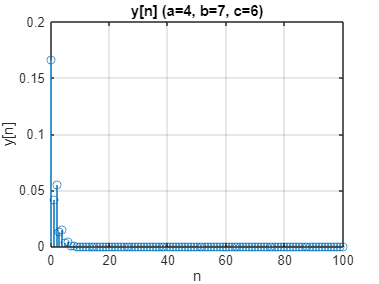


n_start_y = 0;
n_end_y = 100;
n_vals_y = n_start_y:n_end_y;

y_n_theoretical = zeros(size(n_vals_y));

for i = 1:length(n_vals_y)
    current_n = n_vals_y(i);
    if current_n >= 0
        sum_terms = 0;
        for j = 1:length(R); sum_terms = sum_terms + R(j) * (P(j)^current_n); end
        if current_n == 0 && ~isempty(K_direct); sum_terms = sum_terms + K_direct; end
        y_n_theoretical(i) = sum_terms;
    end
end

figure;
stem(n_vals_y, real(y_n_theoretical));
title(sprintf('y[n] (a=%d, b=%d, c=%d)', a, b, c));
xlabel('n');
ylabel('y[n]');
grid on;
xlim([n_start_y n_end_y]);

5) filter komutu kullanımı, x[n] = (1/2)^n u[n] n = −100, ... ,100 için örnekler oluşturup xn adından bir vektöre kaydet, filter ile çıkış sinyalini hesapla, n = -20, ... , 20 için stem ile çizdir

filter açıklama:

y = filter(b, a, x): 

b: pay katsayıları vektörü, a: payda katsayıları vektörü, y[n] in katsayısı yani 1 ile başlatılmalı, x: input olarak verilen sinyal, y: output olarak çıkan sinyal

y[n] = -(1/a)y[n-1] + (1/b)y[n-2] + (1/c)x[n] ; y[n] + (1/a)y[n-1] - (1/b)y[n-2] = (1/c)x[n]

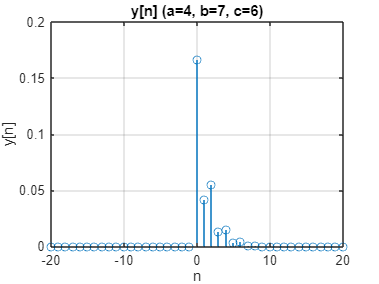

n_start_x = -100;
n_end_x = 100;
n_vals_x = n_start_x:n_end_x; 
xn = zeros(size(n_vals_x));
idx_n_ge_0 = find(n_vals_x >= 0);
xn(idx_n_ge_0) = (1/2) .^ n_vals_x(idx_n_ge_0);

b_filter = [1/c];
a_filter = [1, (1/a), -(1/b)];

yn_filter = filter(b_filter, a_filter, xn);
plot_n_start = -20;
plot_n_end = 20;
plot_n_range = plot_n_start:plot_n_end;

idx_plot_start = find(n_vals_x == plot_n_start);
idx_plot_end = find(n_vals_x == plot_n_end);

figure;
stem(n_vals_x(idx_plot_start:idx_plot_end), yn_filter(idx_plot_start:idx_plot_end));
title(sprintf('y[n] (a=%d, b=%d, c=%d)', a, b, c));
xlabel('n');
ylabel('y[n]');
grid on;
xlim([plot_n_start plot_n_end]);

6) conv komutu kullanımı, xn 5. ile aynı, çıkış sinyali conv ile hesapla, stem ile çizdir

y = conv(x, h): x: input sinyali, h: impulse response, y: output sinyali

- conv komutunun döndürdüğü y vektörünün uzunluğu x ve h ın uzunluklarına bağlıdır (len(x)+len(h)-1)

- eğer x'in ilk indeksinin değeri nx ise ve h'ın ilk indeksinin değeri nh ise, y'nin ilk indeksinin değeri nx+nh olacak. bu conv sonucunun doğru n'lere denk getirmek için yani çizimde önemli

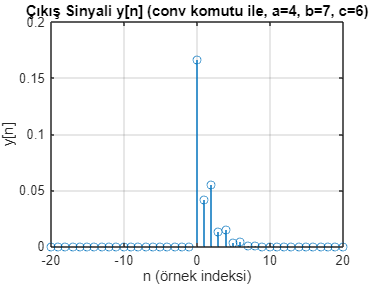

yn_conv = conv(xn, h_n);
nx_start = n_start_x; 
nh_start = n_start;
ny_conv_start = nx_start + nh_start;
ny_conv_vals = ny_conv_start : (ny_conv_start + length(yn_conv) - 1);

plot_n_start = -20;
plot_n_end = 20;
plot_n_range = plot_n_start:plot_n_end;

idx_conv_plot_start = find(ny_conv_vals == plot_n_start);
idx_conv_plot_end = find(ny_conv_vals == plot_n_end);

figure;
stem(ny_conv_vals(idx_conv_plot_start:idx_conv_plot_end), ...
    yn_conv(idx_conv_plot_start:idx_conv_plot_end));
title(sprintf('Çıkış Sinyali y[n] (conv komutu ile, a=%d, b=%d, c=%d)', a, b, c));
xlabel('n (örnek indeksi)');
ylabel('y[n]');
grid on;

xlim([plot_n_start plot_n_end]);

7) x[n] = (1/2)^n u[n] giriş sinyalinden n = −100, −99, . . . , 99, 100  için örnekler oluşturup xn adından bir vektöre kaydedin. Teorik olarak  elde ettiğiniz h[n] sinyalinden n = −100, −99, . . . , 99, 100 için  örnekler oluşturup hn adında bir vektöre kaydedin. N = 512 için xn  vektörüne fft komutu uygulayın. Elde ettiğiniz X[k] vektörü aşağıda  belirtildiği gibi X(ejω) fonksiyonundan ayrık örneklere karşılık  gelmektedir: X[k] = X(ejω)|ω= 2π(k−1)/N , k = 1, 2 . . . , 511, 512.  X[k] vektörünü kullanarak |X(ejω)| fonksiyonun grafiğini Matlab’da plot  komutunu kullanarak çizdirin. Aynı işlemleri h[n] için tekrarlayın.  Zamanda evrişimin frekansta çarpmaya karşılık gelmesi özelliğini  kullanarak Y (ejω)’yı elde edin ve |Y (ejω)| fonksiyonunun grafiğini  Matlab’da plot komutunu kullanarak çizdirin. ifft komutunu kullanarak  y[n] sinyalini elde edin ve grafiğini çizdirin.

8) Önceki dört maddedeki çıktıları Matlab’da aynı grafikte çizdirin. Sonuçları karşılaştırın.